Q-7

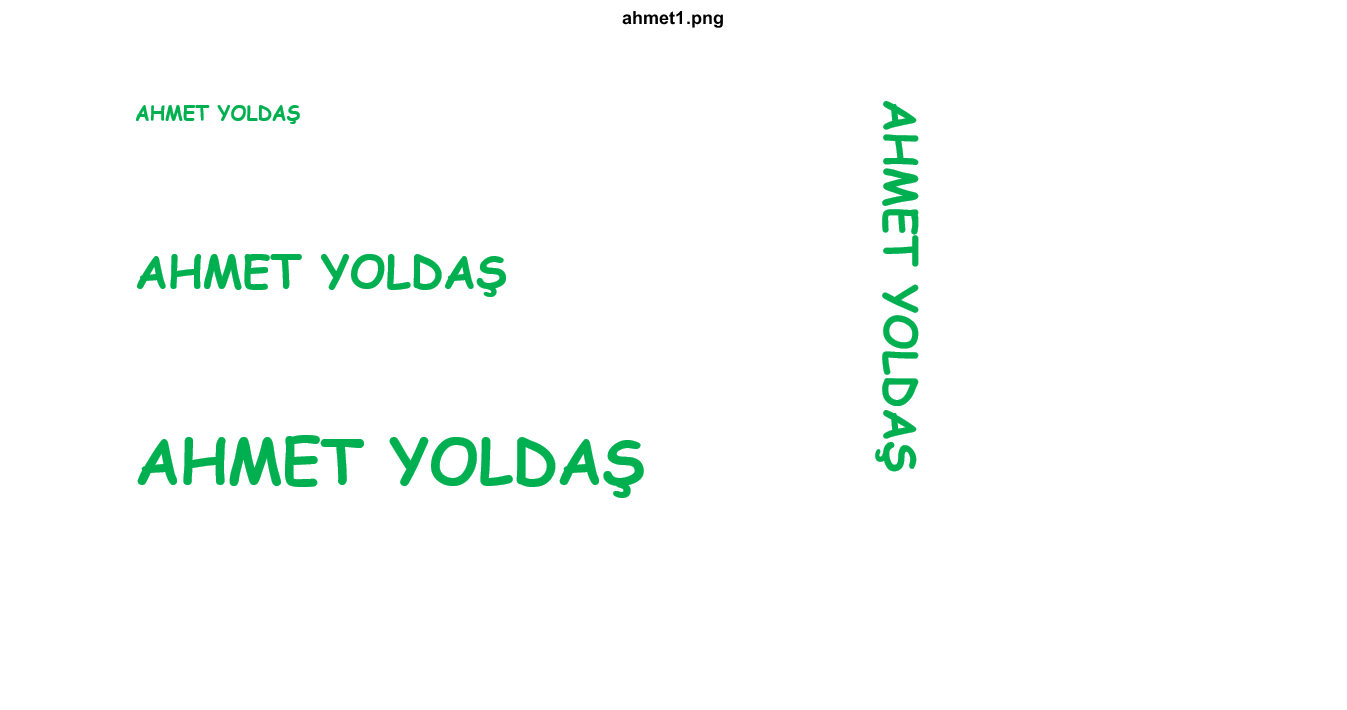

ahmet=imread('C:\Users\ahmet\Desktop\ahmet1.png');
figure;
imshow(ahmet);
title('ahmet1.png');

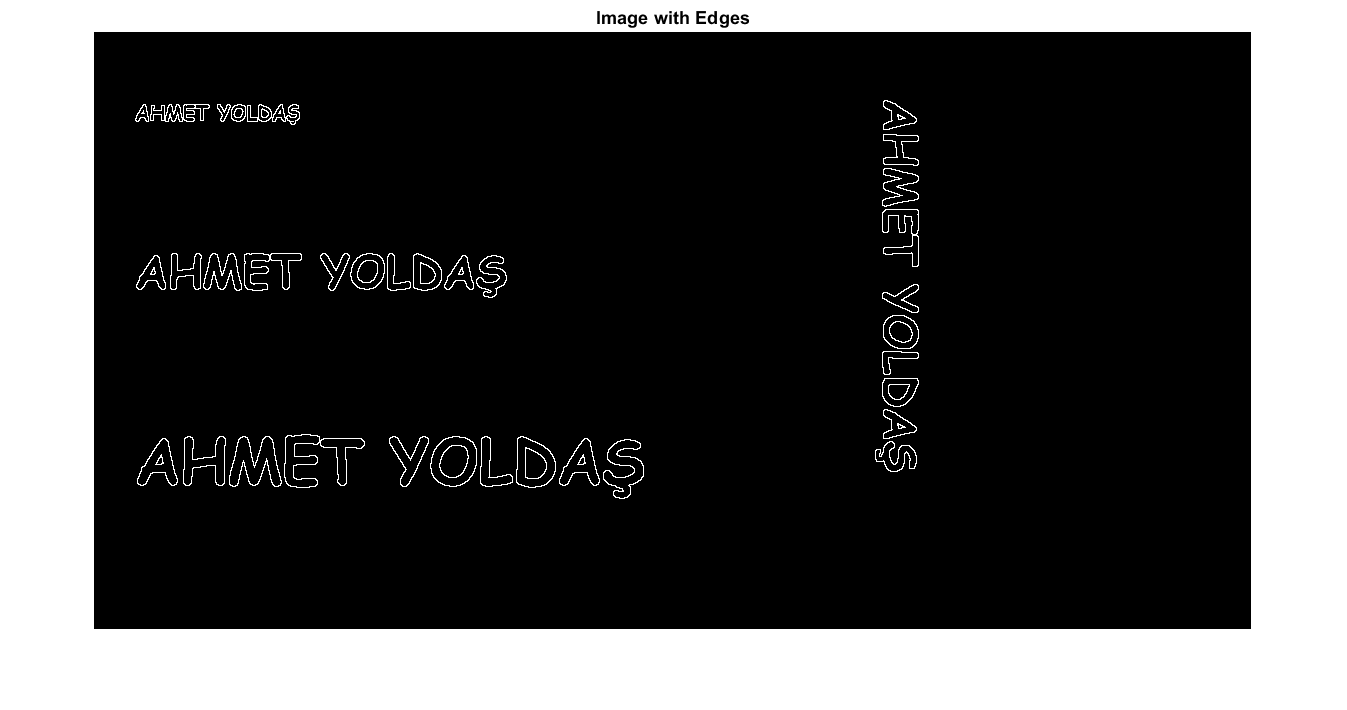

binary=im2bw(ahmet,0.5);
reverse_binary=~binary;
imfilter = binary * 0; 
se1=[1 1 1; 1 1 1; 1 1 1];
for r=2:529
    for c=2:846
        patch = reverse_binary(r-1 : r+1, c-1:c+1);
         patchfilt = patch .* se1;
          patchfilt=sum(patchfilt(:));
             if (patchfilt > 0)
              imfilter(r,c) = 1;
             else
              imfilter(r,c) = 0;
        end 
        
    end
end

 
 
edge=imfilter-reverse_binary;
imshow(edge);
title("Image with Edges")